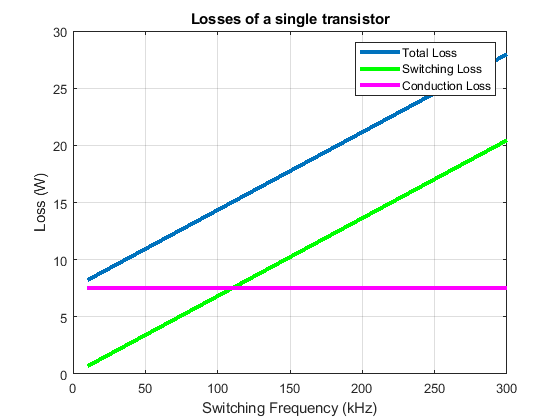

Rds = 129e-3; %150C
K = 4;
Iout = 20;
Vin = 400;
Vout = 200;
NumParallel = 4;
tr = 10e-9;
fsw = 10e3:10e3:300e3;
IperTr = Iout / NumParallel;
Pconds = (IperTr^2 + (K*IperTr)^2 / 12) * Rds;
Pswitch = 2*(88e-12 * Vin^2 + Vin*IperTr*tr) * fsw;
[~,m] = size(fsw);
Pcond = (Pconds*ones(m));
Ptransistor = Pconds + Pswitch;
figure;
plot(fsw/1e3,Ptransistor,fsw/1e3,Pswitch,'g',fsw/1e3,Pcond,'m','LineWidth',3)
legend('Total Loss', 'Switching Loss', 'Conduction Loss')
xlabel('Switching Frequency (kHz)')
ylabel('Loss (W)')
title('Losses of a single transistor')
grid on


Pout = Vout * Iout;
Efficiency = Pout / (Pout + NumParallel*30*2)*100

Efficiency = 94.3396